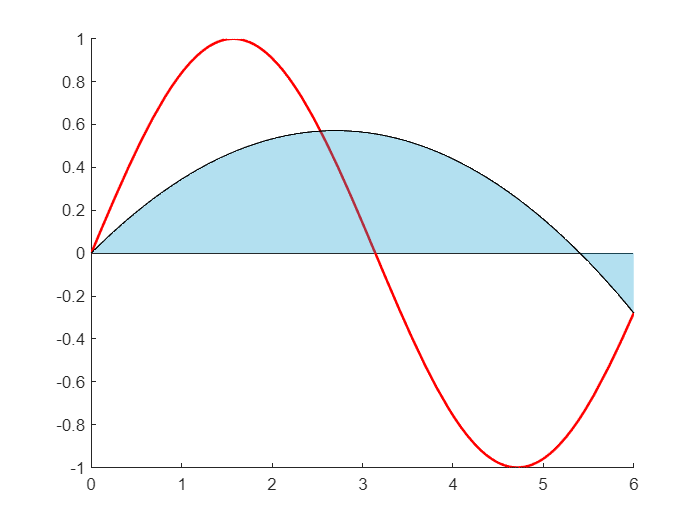

% metodo simpson 1/3 simple
close all
syms x
f = sin(x);
a = 0;
b = 6;
vars = symvar(f);
m=(a+b)/2;
r1 = subs(f,vars(1),a);
r2 = subs(f,vars(1),b);
r3 = 4*subs(f,vars(1),m);
I=(b-a)*double(r1+r2+r3)/6;
coef = polyfit([a,b,m],[double(r1),double(r2),double(r3)],2);
hold on
fplot(f,[a,b],'LineWidth',1.5,"Color","r")
fgraf = @(x) (coef(1)).*x.^2+ coef(2).*x+coef(3);
X = a:0.01:b;
Y = fgraf(X);
areasombreada = area(X,Y);
areasombreada.FaceColor = [0.01, 0.6, 0.8];
areasombreada.FaceAlpha = 0.3;
hold off

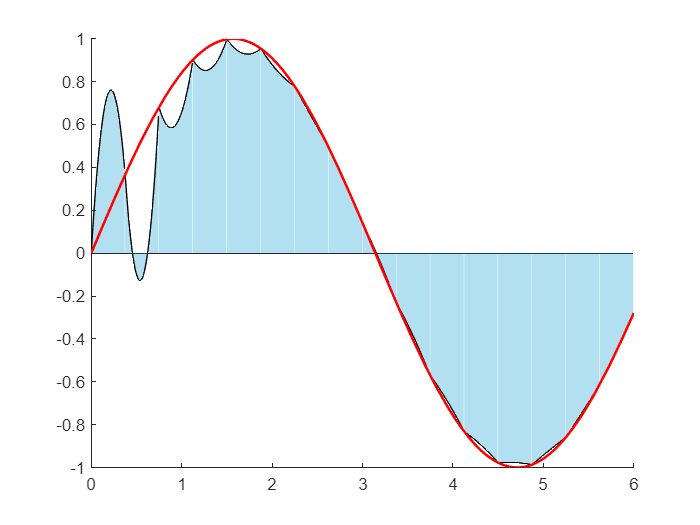

% metodo simpson 1/3 compuesto
close all
syms x
f = sin(x);
a = 0;
b = 6;
n = 16;
h=(b-a)/n;
x0 = a;
vars = symvar(f);
r = numel(a:h:b);
for i = 1:r-1
    x1 = x0+h;
    r1 = subs(f,vars(1),x0);
    r2 = subs(f,vars(1),x1);
    r3 = 4*subs(f,vars(1),(x1+x0)/2);
    coef = polyfit([x0,x1,(x1-x0)/2],[double(r1),double(r2),double(r3)],2);
    hold on
    fgraf = @(x) (coef(1)).*x.^2+ coef(2).*x+coef(3);
    X = x0:0.01:x1;
    Y = fgraf(X);
    areasombreada = area(X,Y);
    areasombreada.FaceColor = [0.01, 0.6, 0.8];
    areasombreada.FaceAlpha = 0.3;
    x0 = x1;
end
fplot(f,[a,b],'LineWidth',1.5,"Color","r")
hold off

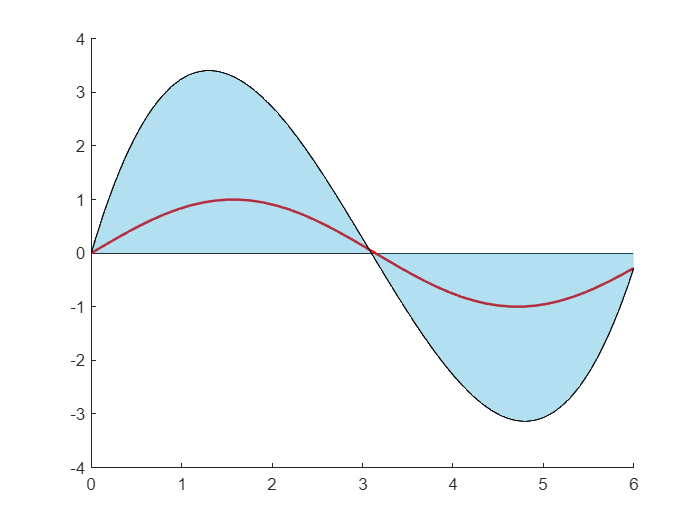

% metodo simpson 3/8 simple
close all
syms x
f = sin(x);
a = 0;
b = 6;
vars = symvar(f);
m=(b-a)/3;
r1 = subs(f,vars(1),a);
r2 = subs(f,vars(1),b);
r3 = 3*subs(f,vars(1),(2*a+b)/3);
r4 = 3*subs(f,vars(1),(a+2*b)/3);
I=(b-a)*double(r1+r2+r3)/6;
coef = polyfit([a,b,(2*a+b)/3,(a+2*b)/3],[double(r1),double(r2),double(r3),double(r4)],3);
hold on
fplot(f,[a,b],'LineWidth',1.5,"Color","r")
fgraf = @(x) (coef(1)).*x.^3+ coef(2).*x.^2+coef(3).*x+coef(4);
X = a:0.01:b;
Y = fgraf(X);
areasombreada = area(X,Y);
areasombreada.FaceColor = [0.01, 0.6, 0.8];
areasombreada.FaceAlpha = 0.3;
hold off

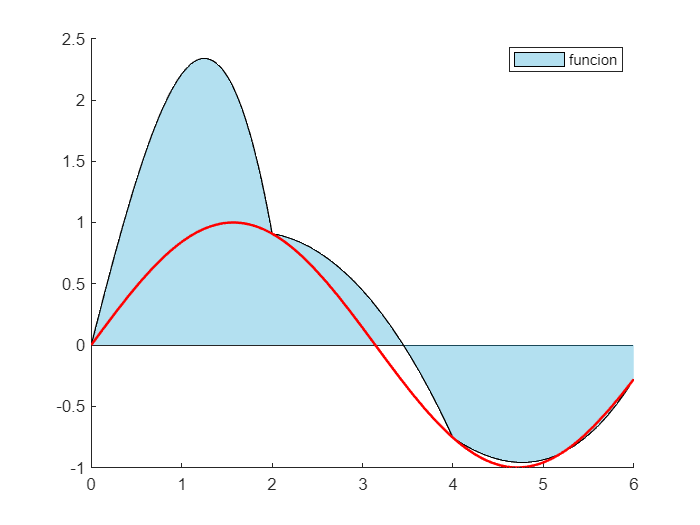

% metodo simpson 3/8 compuesto
close all
n = 3;
h = (b-a)/n;
x0 = a;
vars = symvar(f);
r = numel(a:h:b);
for i = 1:r-1
    x1 = x0+h;
    r1 = subs(f,vars(1),x0);
    r2 = 3*subs(f,vars(1),(2*x0-x1)/3);
    r3 = 3*subs(f,vars(1),(x0-2*x1)/3);
    r4 = subs(f,vars(1),x1);
    coef = polyfit([x0,(2*x0-x1)/3,(x0-2*x1)/3,x1],[double(r1),double(r2),double(r3),double(r4)],3);
    hold on
    fgraf = @(x) (coef(1)).*x.^3+coef(2).*x.^2+coef(3).*x+coef(4);
    X = x0:0.01:x1;
    Y = fgraf(X);
    areasombreada = area(X,Y);
    legend('aproximacion',"Location","best")
    areasombreada.FaceColor = [0.01, 0.6, 0.8];
    areasombreada.FaceAlpha = 0.3;
    x0 = x1;
end
fplot(f,[a,b],'LineWidth',1.5,"Color","r")
legend('funcion',"Location","best")
hold off